tvals = [1 2 2.5 4];
qvals = [45 90 -45 45];

v1 = 0;
vn = 0;
print_info = true;

coeffs = splines_norm_compute_coeffs(tvals, qvals, v1, vn, print_info)

$$h = \left(\begin{array}{ccc} t_{2}-t_{1} & t_{3}-t_{2} & t_{4}-t_{3} \end{array}\right)$$

We need 3 cubic poly
For each k-th cubic function:	q_k(tau) = a_k3*tau^3 + a_k2*tau^2 + a_k1*tau + a_k0
	tau € [0, 1]; tau = t-t_k/h_k; h_k = t_k+1 - t_k; t € [t_k, t_k+1]First at all we compute the intermediate velocities v2 ... vn-1
To do that we write the following linear system Ax=b where x=[v2 ... vn-1]

$$A = \left(\begin{array}{cc} 2\,t_{3}-2\,t_{1} & t_{2}-t_{1}\\ t_{4}-t_{3} & 2\,t_{4}-2\,t_{2} \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{\left(3\,q_{1}-3\,q_{2}\right)\,\left(t_{2}-t_{3}\right)}{t_{1}-t_{2}}-\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{1}-t_{2}\right)}{t_{2}-t_{3}}\\ -\frac{\left(3\,q_{2}-3\,q_{3}\right)\,\left(t_{3}-t_{4}\right)}{t_{2}-t_{3}}-\frac{\left(3\,q_{3}-3\,q_{4}\right)\,\left(t_{2}-t_{3}\right)}{t_{3}-t_{4}} \end{array}\right)$$

By replacing symbols with numbers we obtain:
 

$$A = \left(\begin{array}{cc} 3 & 1\\ \frac{3}{2} & 4 \end{array}\right)$$

$$b = \left(\begin{array}{c} -\frac{1485}{2}\\ -1125 \end{array}\right)$$

With the result:


$$x = \left(\begin{array}{c} -\frac{1230}{7}\\ -\frac{3015}{14} \end{array}\right)$$

All the velocities at each knots are the following:


$$velocities = \left(\begin{array}{c} 0\\ -\frac{1230}{7}\\ -\frac{3015}{14}\\ 0 \end{array}\right)$$

Now we compute coefficients of each cubic functionFor each function to compute a2 and a3 we have to solve the following linear system (Ax=b)

$$A\_\_ = \left(\begin{array}{cc} 1 & 1\\ \frac{2}{h_{i}} & \frac{3}{h_{i}} \end{array}\right)$$

$$b\_\_ = \left(\begin{array}{c} q_{j}-q_{i}-h_{i}\,v_{i}\\ v_{j}-v_{i} \end{array}\right)$$

Where j = i+1 and h_i = t_j - t_i
Others coefficients are instead immediately computable:
a0 = q_i
a1 = v_i * h_i
Coefficients of all cubic functions -------------------Symbolic Cubic 1 parameters:
a0 = 45.000000 
a1 = 0.000000 
a2 = 310.714286 
a3 = -265.714286 
Symbolic Cubic 2 parameters:
a0 = 90.000000 
a1 = -87.857143 
a2 = -121.607143 
a3 = 74.464286 
Symbolic Cubic 3 parameters:
a0 = -45.000000 
a1 = -323.035714 
a2 = 916.071429 
a3 = -503.035714 
-------------------------------------------------------

$$coeffs = \left(\begin{array}{cccc} 45 & 0 & \frac{2175}{7} & -\frac{1860}{7}\\ 90 & -\frac{615}{7} & -\frac{3405}{28} & \frac{2085}{28}\\ -45 & -\frac{9045}{28} & \frac{12825}{14} & -\frac{14085}{28} \end{array}\right)$$

N = 4

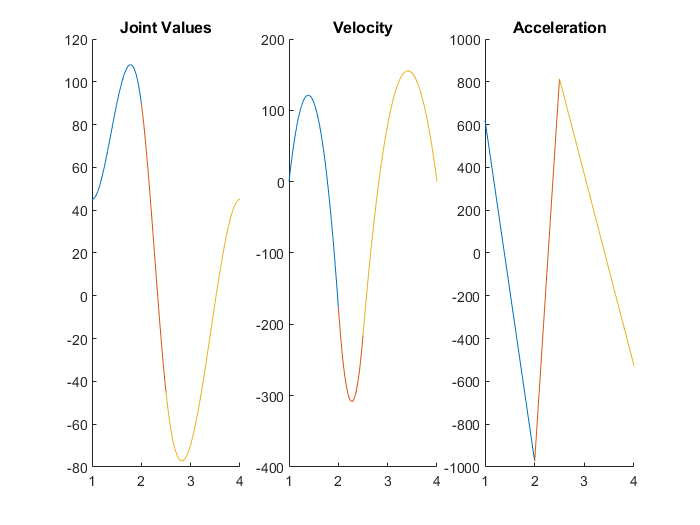

spline_plot_norm(tvals, coeffs)